# Chapter 6, Section 4 (Part 4)

In our last activity, we saw that the orthogonal complement of the row space of matrix $A$ is equal to the nullspace of matrix $A$. Before continuing, let's provide a definition of the orthgonal complement again.

**Definition:** Let $W$ be a subspace of an inner product space $V$ (a vector space with an inner product). Then,


$$W^\bot=\{\textbf v\in V:\ \textbf v\cdot \textbf w=0 \text{ for all } \textbf w\in W\}$$


is called the orthogonal complement of $W$. In other words, the orthogonal complement of $W$ is the collection of all vectors in $V$ that are orthgonal to every vector in $W$.

We showed that if a vector $\textbf v\in V$ is orthogonal to each vector in a basis $B_W=\left\{\textbf w_1\, \textbf w_2,\ \ldots,\ \textbf w_m\right\}$, then it lies in the orthogonal complement of $W$; that is, $\textbf v\in W^\bot$. Let $\textbf w_1,\ \textbf w_2\,\ldots,\ \textbf w_m$ be a collection of vectors in $V$ and let $W=\text{span}\{\textbf w_1\,\textbf w_1,\ \ldots,\ \textbf w_m\}$. If $\textbf v$ is orthogonal to each $\textbf w_i$, for $i=1,2,\ldots,m$,  then $\textbf v$ will lie in the orthogonal complement of $W$; that is, $\textbf v\in W^\bot$. Now, we will show that this is also true if $\textbf v$ is orthogonal to each vector is a set that spans $W$.

**Lemma 1:** Let $W=\text{span}\{\textbf w_1,\ \textbf w_2,\ \ldots,\ \textbf w_m\}$ be a subspace of an inner product space $V$. If $\textbf v\in V$ and $\textbf v$ is orthogonal to $\textbf w_1,\ \textbf w_2,\ \ldots,\ \textbf w_m$ and $\textbf v\in W^\bot$.

**Proof:** Let $\textbf w \in W$. Because $W=\text{span}\{\textbf w_1,\textbf w_2,\ \ldots,\ \textbf w_m\}$, we can write:


$$\textbf w=c_1\textbf w_1+c_2\textbf w_2+\cdots+c_m\textbf w_m$$


Now we will take the dot product of both sides with respect to $\textbf v$.


$$\begin{array}{rcl}
\textbf v\cdot\textbf w&=&\textbf v\cdot(c_1\textbf w_1+c_2\textbf w_2+\cdots+c_m\textbf w_m)\\
\textbf v\cdot\textbf w&=& c_1(\textbf v\cdot\textbf w_1)+c_2(\textbf v\cdot\textbf w_2)+\cdots+c_m(\textbf v\cdot\textbf w_m)
\end{array}$$


Now, because $\textbf v$ is orthogonal to each of the vectors $\textbf w_i$ for $i=1, 2, \ldots, m$, we know that $\textbf v\cdot\textbf w_i=0$ for $i=1,2,\ldots,m$, so


$$\begin{array}{rcl}
\textbf v\cdot\textbf w&=&c_1(0)+c_2(0)+\cdots+c_m(0)\\
\textbf v\cdot\textbf w&=&0
\end{array}$$


Therefore, $\textbf v$ is orthogonal to $\textbf w$, which was any vector $\textbf w\in W$. Therefore, we've shown that $\textbf v\in W^\bot$.

# A Fundamental Set of Matrices

In several examples in Chapter 6, Section 4, we've shown that the orthogonal complement of the row space of a matrix $A$ is equal to the nullspace of matrix $A$. Now, let's show a proof.

# Theorem 1

Let $A$ be an $m\times n$ matrix. Then, $\text{row}(A)^\bot=N(A)$; that is, the orthogonal complement of the row space of matrix $A$ is equal to the nullspace of matrix $A$. 

**Proof:** Let $A$ be an $m\times n$ matrix. We have two things we need to show:

- 
$$\text{row}(A)^\bot\subset N(A)$$


- 
$$N(A)\subset \text{row}{(A)^\bot$$


**Part 1:** Let $\textbf x\in\text{row}(A)^\bot$. Now, we need to show that $\textbf x\in N(A)$. First, let's create our $m\times n$ matrix $A$.


$$A=\pmatrix{a_{11} & a_{12}&\cdots&a_{1n}\cr
a_{21} & a_{22} & \cdots & a_{2n}\cr
\vdots & \vdots & \ddots & \vdots\cr
a_{m1} & a_{m2} & \cdots & a_{mn}}$$


Now, the row space of matrix $A$ is all linear combinations of the rows of matrix $A$. That is,


$$\text{row}(A)=\text{span}\{(a_{11},a_{12},\ldots,a_{1n}), (a_{21},\ a_{22},\ldots,a_{2n}),\ \cdots,\ (a_{m1},a_{m2},\ldots,a_{mn})\}$$


Each of these vectors is in the row space of matrix $A$, and because $\textbf x\in \text{row}(A)^\bot$, this means that $\textbf x$ is orthogonal to each of these row vectors. This means that:


$$\begin{array}{rcl}
(a_{11}, a_{12},\cdots,a_{1n})\cdot(x_1,x_2,\cdots,x_n)&=&0\\
(a_{21}, a_{22},\cdots,a_{2n})\cdot(x_1,x_2,\cdots,x_n)&=&0\\
\vdots&=&\vdots\\
(a_{m1}, a_{m2},\cdots,a_{mn})\cdot(x_1,x_2,\cdots,x_n)&=&0
\end{array}$$


Using the dot product method for multiplying a matrix times a vector, this can be written as:


$$\pmatrix{a_{11} & a_{12}&\cdots&a_{1n}\cr
a_{21} & a_{22} & \cdots & a_{2n}\cr
\vdots & \vdots & \ddots & \vdots\cr
a_{m1} & a_{m2} & \cdots & a_{mn}}\pmatrix{x_1\cr x_2\cr\vdots\cr x_n}=\pmatrix{0\cr 0\cr \vdots\cr 0}$$


which is equivalent to


$$A\textbf x=\textbf 0$$


which means that $\textbf x\in N(A)$. Thus, we have proved that $\text{row}(A)^\bot\subset N(A)$.

**Part 2:** Part 2 flows easily from what we've shown in Part 1. Let $\textbf x\in N(A)$. Then


$$A\textbf x=\textbf 0$$


which can be written as


$$\pmatrix{a_{11} & a_{12}&\cdots&a_{1n}\cr
a_{21} & a_{22} & \cdots & a_{2n}\cr
\vdots & \vdots & \ddots & \vdots\cr
a_{m1} & a_{m2} & \cdots & a_{mn}}\pmatrix{x_1\cr x_2\cr\vdots\cr x_n}=\pmatrix{0\cr 0\cr \vdots\cr 0}$$


which means that:


$$\begin{array}{rcl}
(a_{11}, a_{12},\cdots,a_{1n})\cdot(x_1,x_2,\cdots,x_n)&=&0\\
(a_{21}, a_{22},\cdots,a_{2n})\cdot(x_1,x_2,\cdots,x_n)&=&0\\
\vdots&=&\vdots\\
(a_{m1}, a_{m2},\cdots,a_{mn})\cdot(x_1,x_2,\cdots,x_n)&=&0
\end{array}$$


Therefore, $\textbf x$ is orthogonal to each row of matrix $A$, which by Lemma 1 above, means that $\textbf x\in \text{row}(A)^\bot$. Therefore, we've shown that $N(A)\subset\text{row}(A)^\bot$.

Because we've shown $\text{row}(A)^\bot\subset N(A)$ and $N(A)\subset\text{row}(A)^\bot$, we've shown that $\text{row}(A)^\bot=N(A)$. We're done.

**Lemma 2: **Let $A$ be an $m\times n$ matrix. Then, $\text{row}(A^T)=\text{col}(A)$.

**Proof:** To prove this fact, let's put $A$ and $A^T$ beside one another.

$A=\pmatrix{a_{11} & a_{12}&\cdots&a_{1n}\cr
a_{21} & a_{22} & \cdots & a_{2n}\cr
\vdots & \vdots & \ddots & \vdots\cr
a_{m1} & a_{m2} & \cdots & a_{mn}}$          and          $A^T=\pmatrix{a_{11} & a_{21}&\cdots&a_{m1}\cr
a_{12} & a_{22} & \cdots & a_{m2}\cr
\vdots & \vdots & \ddots & \vdots\cr
a_{1n} & a_{2n} & \cdots & a_{mn}}$   

Here are the most important things to note:

- Column one of matrix $A$ is row one of matrix $A^T$.

- Column two of matrix $A$ is row two of matrix $A^T$.

- 
$$\cdots$$


- Column $n$ of matrix $A$ is row $n$ of matrix $A^T$.

Therefore, the linear combinations of the columns of matrix $A$ are the same as the linear combinations of the rows of $A^T$, so $\text{row}(A^T)=\text{col}(A)$. 

# Theorem 2

Let $A$ be an $m\times n$ matrix. Then, $\text{col}(A)^\bot=N(A^T)$.

**Proof:** To perform this proof, we let $A$ be an $m\times n$ matrix, then use Theorem 1 to write:


$$\text{row}(A)^\bot=N(A)
$$


Since this is true for all matrices, we'll substitute $A^T$ for $A$ and write:


$$\text{row}(A^T)^\bot=N(A^T)$$


By Lemma 2 above, $\text{row}(A^T)=\text{col}(A)$, so we can make this replacement and write


$$\text{col}(A)^\bot=N(A^T)$$


and we're done.

**Fact:** The four spaces $N(A)$, $N(A^T)$, $\text{col}(A)$, and $\text{col}(A^T)$ are called the **four fundamental spaces **associated with matrix $A$.

# Useful?

Are these theorems and lemmas useful? Let's do an example.

# Example #1

Let


$$\textbf v_1=\pmatrix{2\cr 0\cr 0},\qquad\textbf v_2=\pmatrix{1\cr 2\cr 0},\qquad\text{and}\qquad\textbf v=\pmatrix{3\cr2\cr 2}$$


then let 


$$A=\pmatrix{\textbf v_1 & \textbf v_2}=\pmatrix{2 & 1\cr 0 & 2\cr 0 & 0}\qquad\text{and}\qquad\textbf v=\pmatrix{3\cr 2\cr 2}$$$


Find the orthgonal component of $\textbf v$ orthogonal to $\text{col}(A)$.

**Solution:** Now, we have a couple of choices to perform this task. We could proceed like we did in Example #2 in Chapter 6, Section 4 (Part 3): Find an orthgonal basis for the column space of $A$ using the Gram-Schmidt process, project the vector $\textbf v$ onto the orthogonal basis to get the vectors $\textbf w_1$ and $\textbf w_2$, then let $\textbf w=\textbf w_1+\textbf w_2$, and finally calculate $\textbf u=\textbf v-(\textbf w_1+\textbf w_2)$. 

However, we now have a second choice. Because we know that $\text{col}(A)^\bot=N(A^T)$, we can first compute $N(A^T)$, which is orthogonal to the column space of matrix $A$. 


$$\begin{array}{rcl}
A^T\textbf x&=&\textbf 0\\
\pmatrix{2 & 0 & 0\cr 1 & 2 & 0}\pmatrix{x_1\cr x_2\cr x_3}&=&\pmatrix{0\cr 0}
\end{array}$$


Set up the augmented matrix and row reduce.


$$\pmatrix{2 & 0 & 0 & 0\cr 1 & 2 & 0 & 0}\ \matrix{(1/2)R_1\cr ~}\quad\rightarrow\quad\pmatrix{1 & 0 & 0 & 0\cr 1 & 2 & 0 & 0}\ \matrix{~\cr R_2-R_1}\quad\rightarrow\quad\pmatrix{1 & 0 & 0 & 0\cr 0 & 2 & 0 & 0}\ \matrix{~\cr (1/2)R_2}\quad\text{and}\quad\pmatrix{1 & 0 & 0 & 0\cr 0 & 1 & 0 & 0}$$


Our row reduced matrix is


$$\begin{array}{rcl}
\matrix{x_1\,&x_2\,  & x_3\ & ~}\\
\pmatrix{[1] & 0 & 0 & 0\cr 0 & [1] & 0 & 0}\\
\matrix{p\ & p\ & f\  & ~}
\end{array}$$


Therefore, $x_1=0$, $x_2=0$, and $x_3=\text{free}$. If we choose $x_3=1$, then $\textbf x=(0,0,1)^T$ and $\text{col}(A)^\bot=\text{span}\{(0,0,1)^T\}$. Let's check this with Matlab. Enter $\textbf v_1$ and $\textbf v_2$ and create the matrix $A$.

v1=[2;0;0]; v2=[1;2;0];
A=[v1,v2]

A =      2     1
     0     2
     0     0


Correct. Now, find the nullspace of $A^T$.

x=null(A.','r')

x =      0
     0
     1


Same answer. Now, let's draw an image. The column space is all linear combinations of the columns of $A$, so:


$$\pmatrix{x\cr y\cr z}=s\pmatrix{2\cr 0\cr 0}+t\pmatrix{1\cr 2\cr 0}=\pmatrix{2s+t\cr 2t\cr 0}$$


Now, we will create a figure.

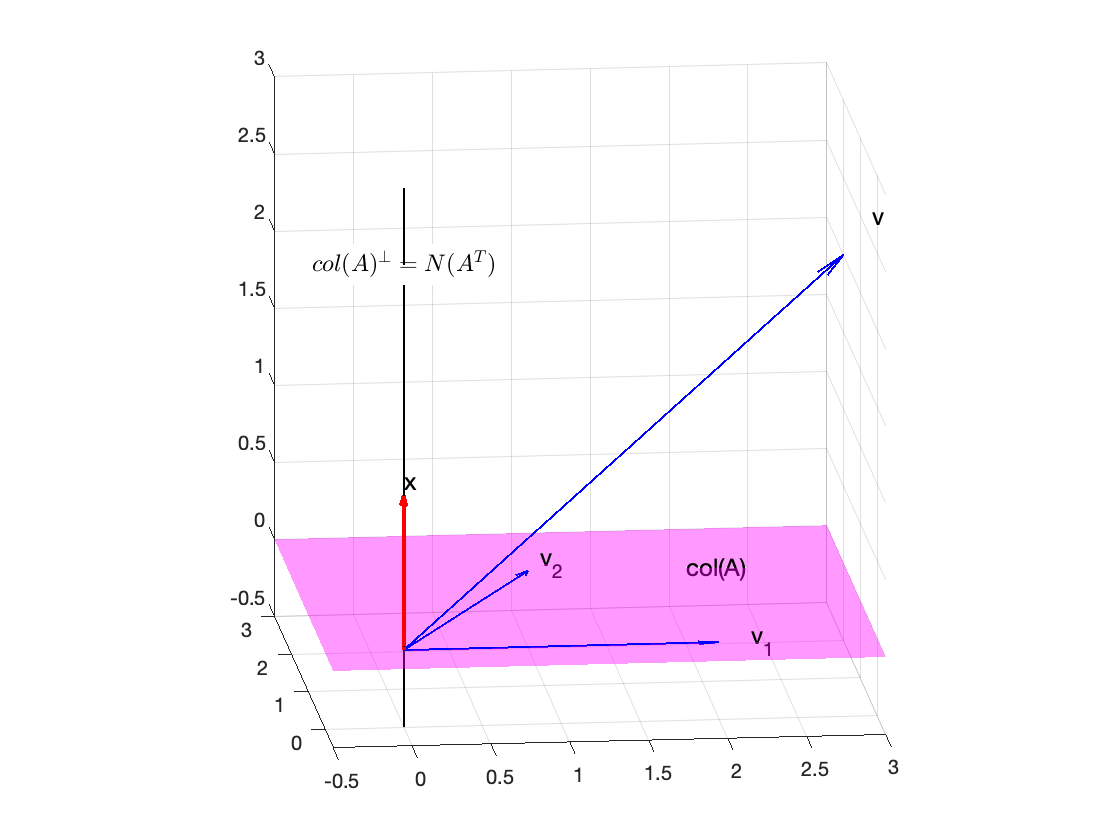

figure
hold on
s=linspace(-4,4,20);
t=linspace(-4,4,20);
[S,T]=meshgrid(s,t);
X=2*S+T;
Y=2*T;
Z=zeros(size(T));
surf(X,Y,Z,'FaceColor','m','EdgeColor','none','FaceAlpha',0.4)
line([0,0],[0,0],[-0.5,3],'LineWidth',1,'Color','k')
quiver3(0,0,0,2,0,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,1,2,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,3,2,2,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,0,0,1,0,'LineWidth',2,'Color','r')
axis equal
axis([-0.5,3,-0.5,3,-0.5,3])
grid on
text(2.2,0,0,'v_1','FontSize',12)
text(1.1,2.2,0,'v_2','FontSize',12)
text(3.2,2.2,2.20,'v','FontSize',12)
text(0,0,1.1,'x','FontSize',12)
text(2,2,0,'col(A)','FontSize',12)
text(0,0,2.5,'$col(A)^\bot=N(A^T)$','FontSize',12,'Interpreter','latex',...
    'HorizontalAlignment','center','BackgroundColor','w')
view([-6.06 13.78])
hold off

Now, to get the orthogonal component of the vector $\textbf v$, all we have to do is to project the vector $\textbf v$ onto the vector $\textbf x$.


$$\begin{array}{rcl}
\textbf u&=&\text{proj}_{\textbf x}\textbf v\\
&=&\frac{\textbf v\cdot\textbf x}{\textbf x\cdot\textbf x}\textbf x\\
&=&\frac{(3,2,2)\cdot(0,0,1)}
{(0,0,1)\cdot(0,0,1)}\pmatrix{0\cr 0\cr 1}\\
&=&\frac21\pmatrix{0\cr 0\cr 1}\\
&=&\pmatrix{0\cr 0\cr 2}
\end{array}$$


 Let's add this vector to our image.

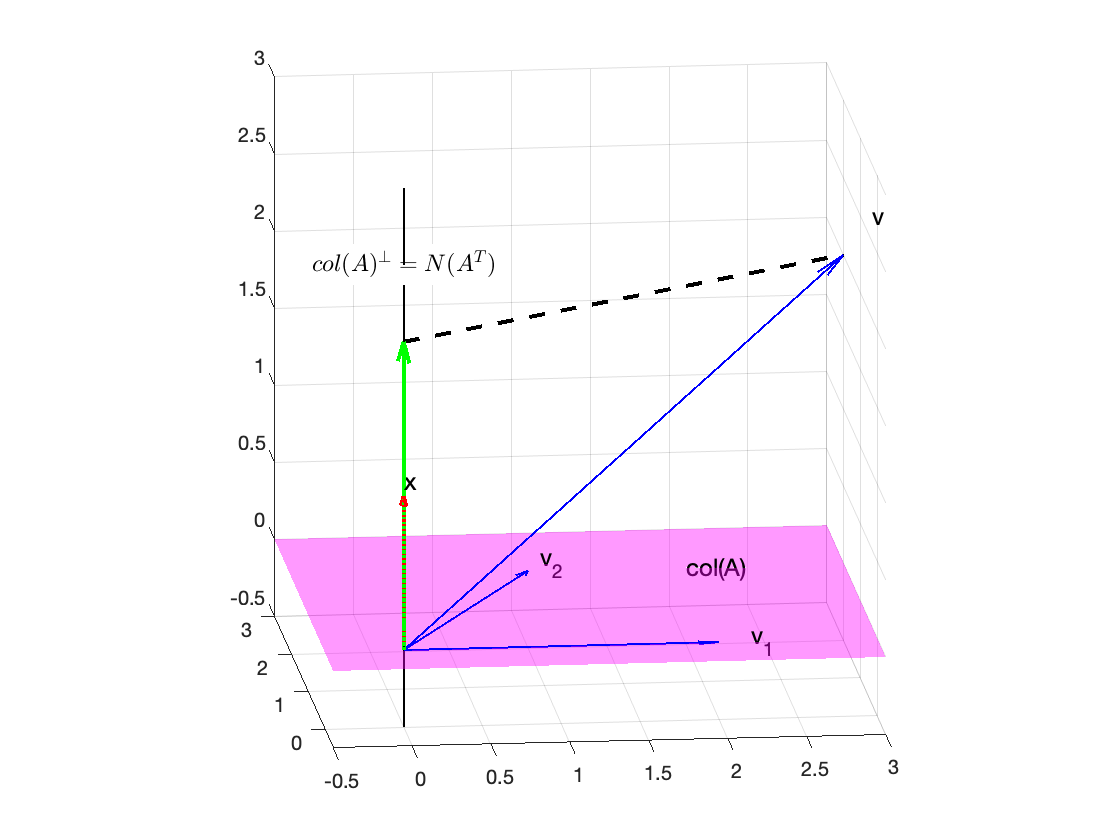

figure
hold on
s=linspace(-4,4,20);
t=linspace(-4,4,20);
[S,T]=meshgrid(s,t);
X=2*S+T;
Y=2*T;
Z=zeros(size(T));
surf(X,Y,Z,'FaceColor','m','EdgeColor','none','FaceAlpha',0.4)
line([0,0],[0,0],[-0.5,3],'LineWidth',1,'Color','k')
quiver3(0,0,0,2,0,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,1,2,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,3,2,2,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,0,0,1,0,'LineWidth',2,'Color','r')
quiver3(0,0,0,0,0,2,0,'LineWidth',2,'Color','g')
line([0,3],[0,2],[2,2],'LineWidth',2,'LineStyle','--','Color','k')
axis equal
axis([-0.5,3,-0.5,3,-0.5,3])
grid on
text(2.2,0,0,'v_1','FontSize',12)
text(1.1,2.2,0,'v_2','FontSize',12)
text(3.2,2.2,2.20,'v','FontSize',12)
text(0,0,1.1,'x','FontSize',12)
text(2,2,0,'col(A)','FontSize',12)
text(0,0,2.5,'$col(A)^\bot=N(A^T)$','FontSize',12,'Interpreter','latex',...
    'HorizontalAlignment','center','BackgroundColor','w')
view([-6.06 13.78])
hold off

 Now, let's rotate our image to give clear evidence that we have found the component of $\textbf v$ orthogonal to $\text{col}(A)$.

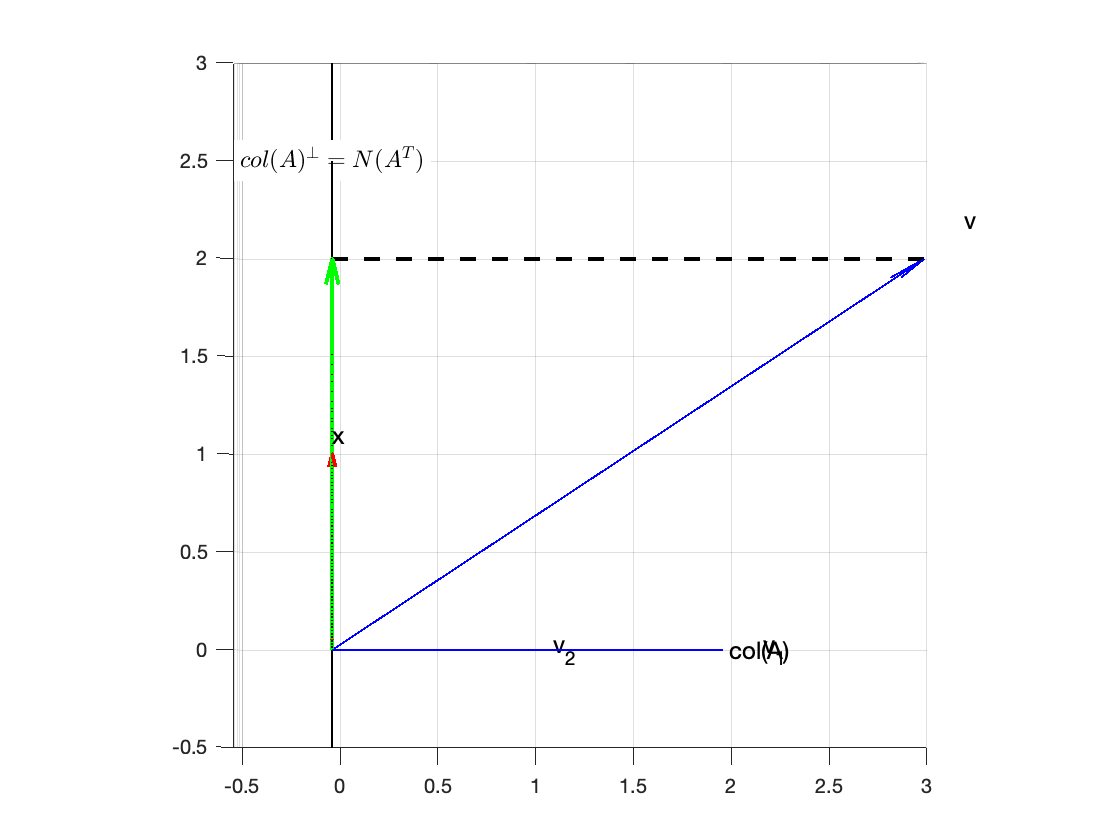

figure
hold on
s=linspace(-4,4,20);
t=linspace(-4,4,20);
[S,T]=meshgrid(s,t);
X=2*S+T;
Y=2*T;
Z=zeros(size(T));
surf(X,Y,Z,'FaceColor','m','EdgeColor','none','FaceAlpha',0.4)
line([0,0],[0,0],[-0.5,3],'LineWidth',1,'Color','k')
quiver3(0,0,0,2,0,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,1,2,0,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,3,2,2,0,'LineWidth',1,'Color','b')
quiver3(0,0,0,0,0,1,0,'LineWidth',2,'Color','r')
quiver3(0,0,0,0,0,2,0,'LineWidth',2,'Color','g')
line([0,3],[0,2],[2,2],'LineWidth',2,'LineStyle','--','Color','k')
axis equal
axis([-0.5,3,-0.5,3,-0.5,3])
grid on
text(2.2,0,0,'v_1','FontSize',12)
text(1.1,2.2,0,'v_2','FontSize',12)
text(3.2,2.2,2.20,'v','FontSize',12)
text(0,0,1.1,'x','FontSize',12)
text(2,2,0,'col(A)','FontSize',12)
text(0,0,2.5,'$col(A)^\bot=N(A^T)$','FontSize',12,'Interpreter','latex',...
    'HorizontalAlignment','center','BackgroundColor','w')
view([0.76 -0.04])
hold off

We will find the facts in this activity extremely useful in our next section.